# Fill in Missing Data

This code loads and plots electricity usage data. 

months=1:10

months =      1     2     3     4     5     6     7     8     9    10


usage=[4.1007 3.8781 2.8459 2.9225 3.7445 4.1711 4.0782 3.7446 2.9883 3.6760]'

usage =     4.1007
    3.8781
    2.8459
    2.9225
    3.7445
    4.1711
    4.0782
    3.7446
    2.9883
    3.6760


monthLabels=["jan" "Feb" "Apr" "May" "Jun" "Jul" "Aug" "Sep" "Nov" "Dec" ]

monthLabels = 1×10 string array
    "jan"    "Feb"    "Apr"    "May"    "Jun"    "Jul"    "Aug"    "Sep"    "Nov"    "Dec"


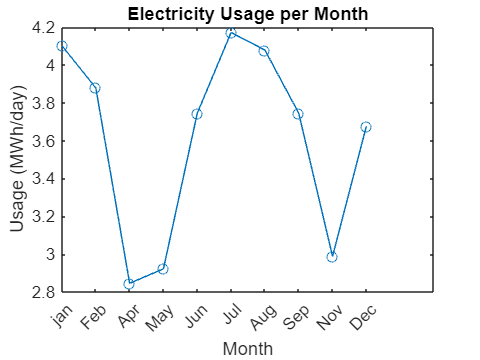

plot(months,usage,"o-")
xticks(months)
xticklabels(monthLabels)
xlabel("Month")
ylabel("Usage (MWh/day)")
xlim([1 12])
title("Electricity Usage per Month");

## Task 1

The vectors `months` and `usage` contain data on electricity consumption for one year. The values in `months` represent the numeric month of the year (1 = January, 2 = February, 3 = March, and so on). Each value in `usage` represents the total electricity consumption for each month in `months`.

You can see in the plot that there are two missing data points, in March and in October.

In this activity, you will find the interpolated usage values at these points using the `interp1` function.

Task

The first missing value is for March, the third month. Assign the value 3 to a variable called `march`.

march=3

march = 3

## Task 2

You can use the `interp1` function to find an interpolated value using the syntax

`yi` `=` `interp1``(``x``,``y``,``xi``)`

where `x` and `y` are the vectors of known data, `xi` is the x value of the desired point, and `yi` is the interpolated value.

Task

Find the interpolated value at `march` using the known data vectors `months` and `usage`. Assign the output to the variable `usageMarch`.

usageMarch=interp1(months,usage,march)

usageMarch = 2.8459

## Task 3

You can add the interpolated point to the existing figure using the `hold` `on` command.

Task

Plot the point at `(``march``,``usageMarch``)` using a circle marker in the current figure. Remember to use the `hold` `off` command when finished plotting.

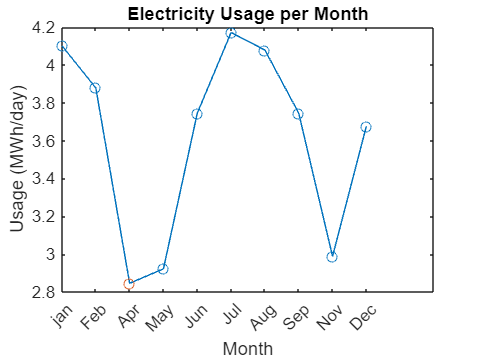

hold on
plot(march,usageMarch,"o")
hold off

## Further Practice

You have found and plotted the interpolated usage for March.

By default, `interp1` performs linear interpolation using two neighboring points. For  example, the two neighbors of March are February and April. You can see  that the interpolated value for March falls exactly on the line between  February and April.

Try to find the interpolated usage for October, the 10th month.

october=3

october = 3

usageoct=interp1(months,usage,october)

usageoct = 2.8459

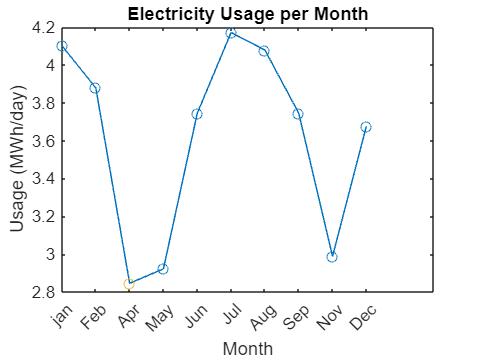

hold on
plot(october,usageoct,"o")
hold off